% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

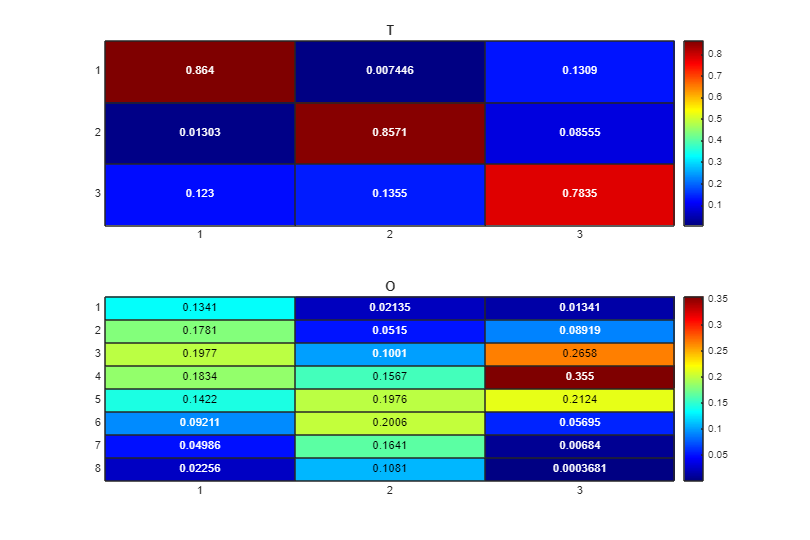

k = 3;
d = 8;
lam = 10;

T = lam * eye(k) + abs(randn(k, k));
T = Stochasticize(T);

O = initialize_emission_matrix(d, k, 1);

% k = 2;
% d = 6;
% 
% T = [.9 .1; .05 .95];
% 
% O = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6;...
% 7/12, 1/12, 1/12, 1/12, 1/12, 1/12];

% 
% k = 3;
% d = 10;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;]';

% k = 3;
% d = 8;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     3/15, 3/20, 3/50;];

pi = findStationaryDistribution(T');


options.method = "standard";
[T, O, pi] = generateHMM(k, d, n, options);


figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(2, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

eig(T)

ans =     0.6557
    1.0000
    0.8489


Generate an observational sequence based on the defined HMM

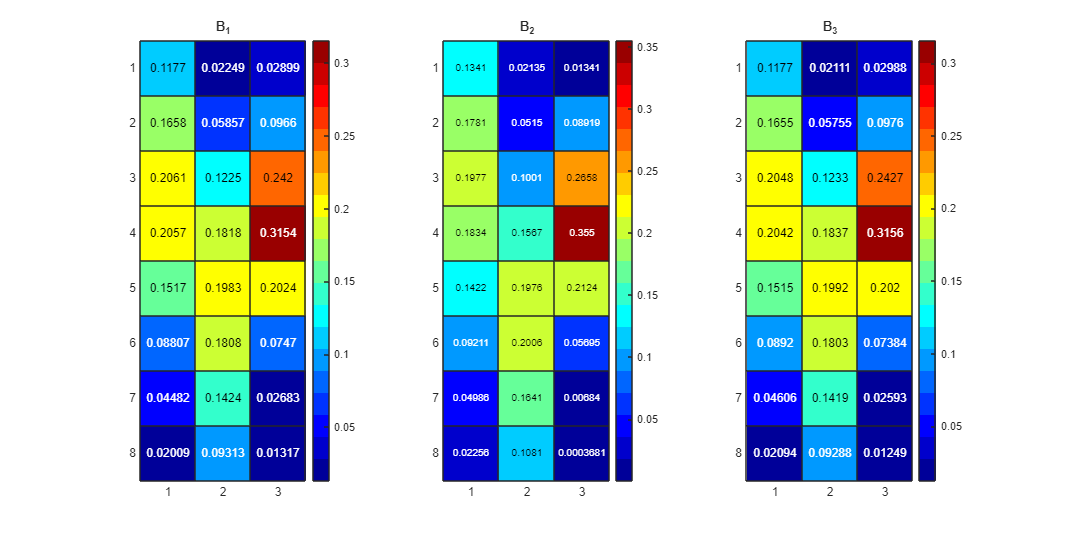

T_seq = 1e5;

[seq,states] = hmmgenerate(T_seq,T',O');

D = {};
D{1} = Stochasticize(O * diag(pi) * T' / inv(diag(T * pi')));
D{2} = O;
D{3} = Stochasticize(O * T);

PlotFactorMatrices(D);


% 
% P3 = cpdgen(U);
% 
% [V, D, W] = eig(T);
% mu = abs(W(:, 1));
% mu = mu ./ sum(mu);
% P2 = O' * T * diag(mu) * O;

Generate Probability Density Tensors

tic
P3 = ProbabilityTensorGenerate(seq, 3, d);
P2 = ProbabilityTensorGenerate(seq, 2, d);
toc

Elapsed time is 0.837418 seconds.




warning('on', 'all')

rho = 0: 0.1 : 1;
iter = 1:length(rho);

lambda = 1e-5;

max_iters = 1000;

Cost = zeros(1, length(iter));

for i = progress(iter)

    % [B1, B2, B3, B4, c, output] = cpd_als_3d_regularized(P3, P2, k, options);
    [B1, B2, B3, B4, output] = als_tensor_factorization(P3, P2, k, rho(i), lambda, max_iters);

    Cost(i) = output.relerr(end);
end

Processing:  000%  |                                        | 0/11it [00:00:00<Inf:NaN:NaN, Inf it/s]


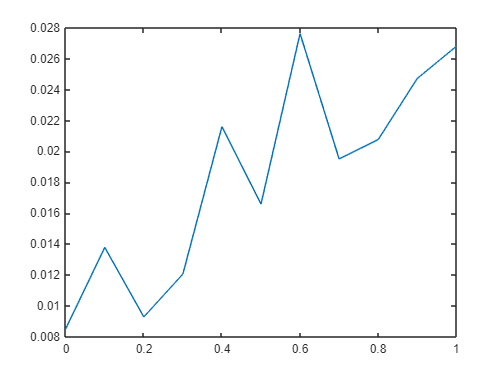

% filteredCost = [];
% for i = 1:length(Cost)
%     if(Cost(i) > 1.6 + (i/length(Cost)))
%         filteredCost = [filteredCost Cost(i)];
%     end
% end
% 
% filteredIndex = find(Cost > 1.6);

figure();
plot(linspace(0, 1, length(Cost)), Cost)


minJ = min(Cost);
minIndex = find(Cost==minJ);

max_iters = 1000;

tic
[B1, B2, B3, B4, output] = als_tensor_factorization(P3, P2, k, rho(minIndex), lambda, max_iters);
toc

Elapsed time is 0.116588 seconds.


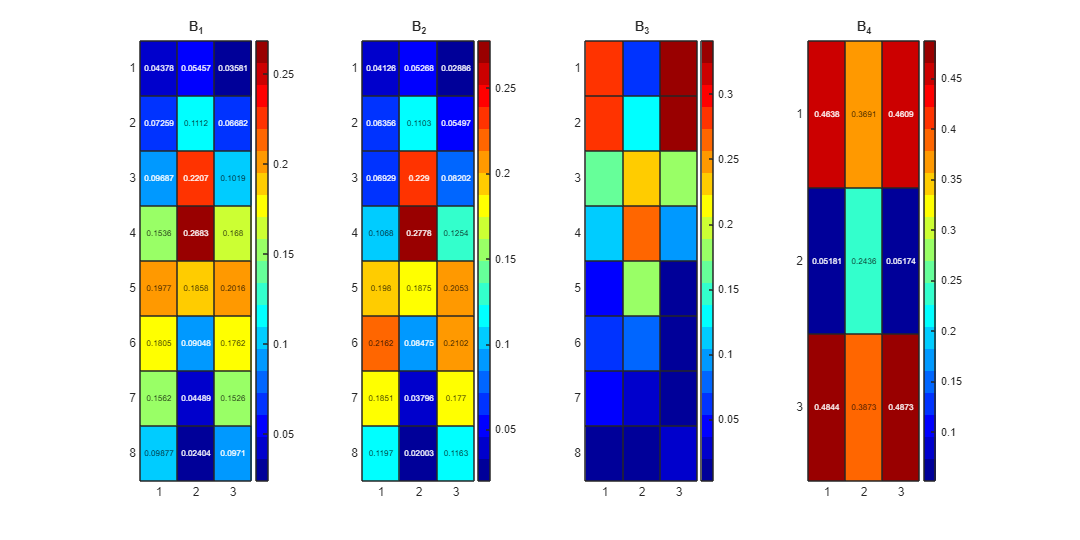


PlotFactorMatrices({B1, B2, B3, B4})


B1 = Stochasticize(B1);
B2 = Stochasticize(B2);
B3 = Stochasticize(B3);
B4 = Stochasticize(B4);

P_best = PermutationFitEmission(O, B2);

B1 = B1 * P_best';
B2 = B2 * P_best';
B3 = B3 * P_best';
B4 = P_best * B4 * P_best';

T_hat = Stochasticize(pinv(B2) * B3);
T_hat = P_best * T_hat * P_best';


norm(T-B4, "fro") + norm(O-B2, "fro")

ans = 1.4041

norm(T-T_hat, "fro") + norm(O-B2, "fro")

ans = 1.3170

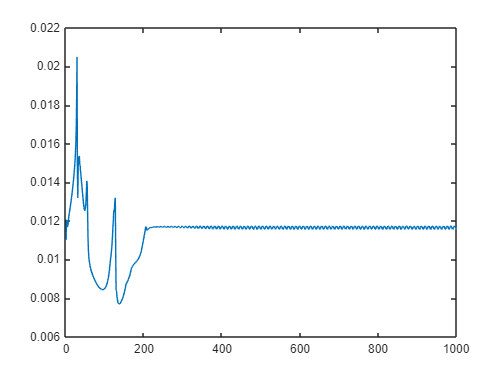


figure()
plot(output.relerr)

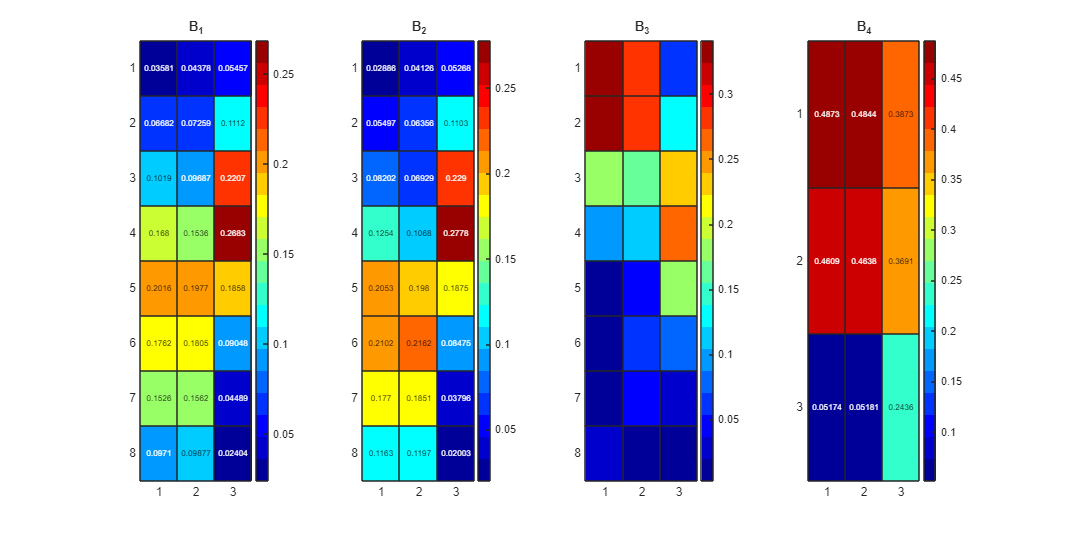

PlotFactorMatrices({B1, B2, B3, B4})

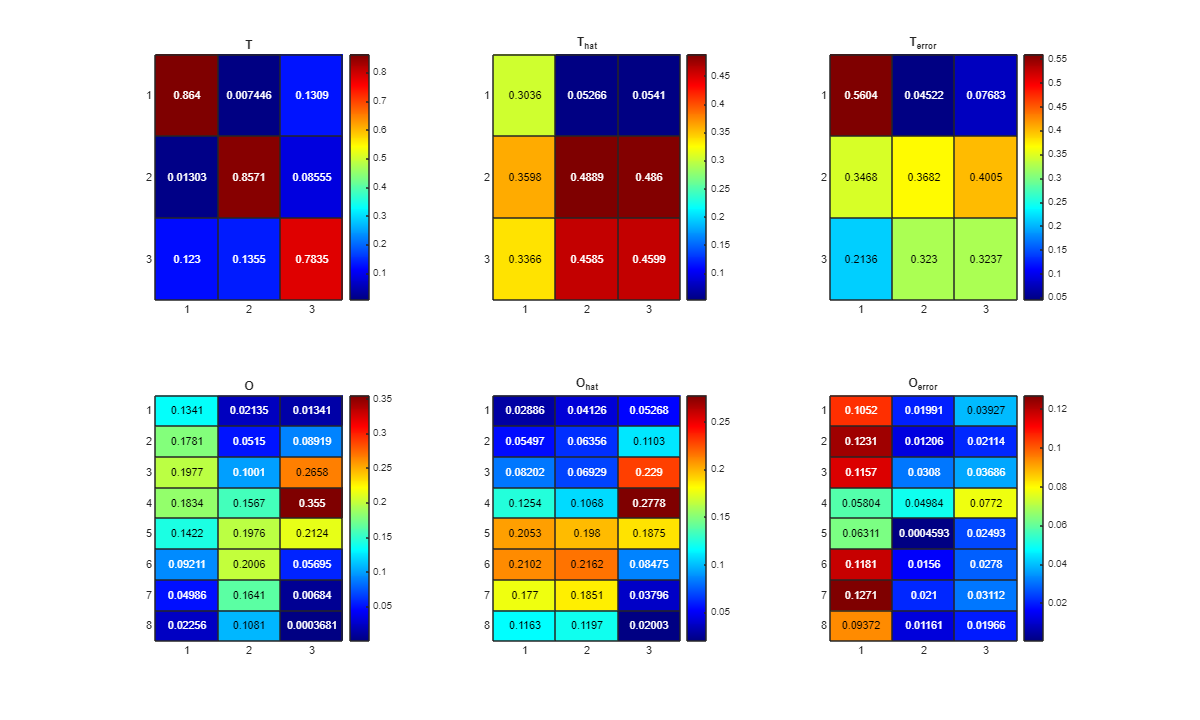

plotHMMError(T, T_hat, O, B2)